## Elastic Transmission model

Exercise

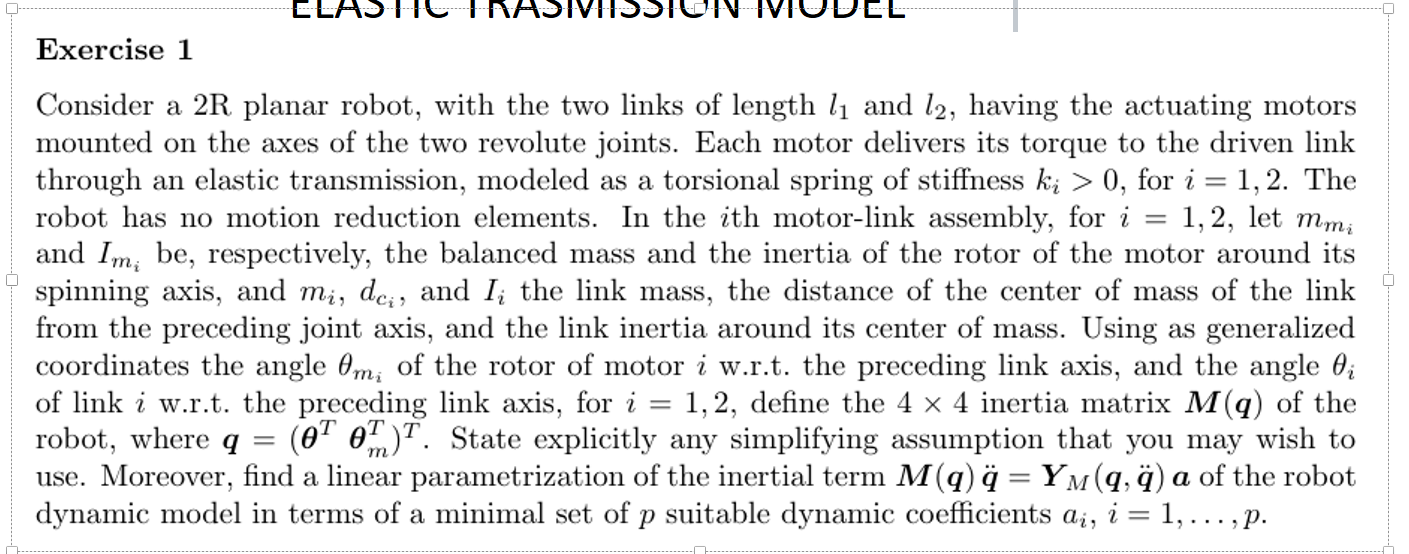

Theory behind

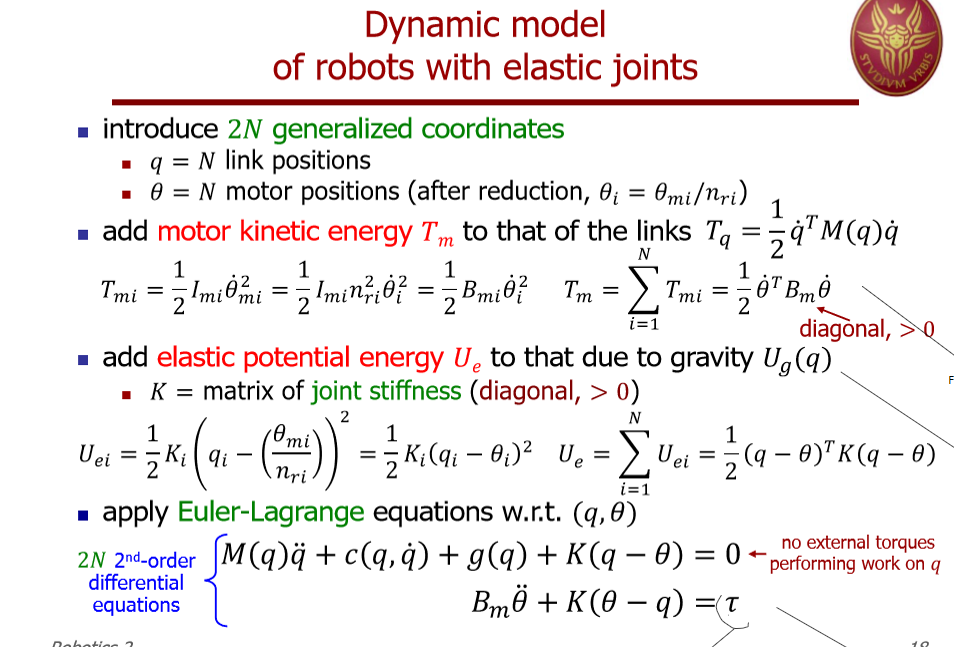

But in this case we don't need to consider the reduction

syms theta1 theta2 dtheta1 dtheta2 l1_m1 l2_m2 l1 l2 d1 d2 I1 I2 g0 m1 m2 m2_m2 positive
syms I1_m1 I2_m2 m1_m2 dtheta_m1 dtheta_m2 positive

% Kinetic Energy of the motors (rotational)
T_m1 = 0.5*(I1_m1)*dtheta_m1^2;
T_m2 = 0.5*m2_m2*l1^2*dtheta1^2 + 0.5*I2_m2*(dtheta1 + dtheta_m2)^2;

% Kinetic energy of the links
T_l1 = 0.5*(I1 + m1*d1^2)*dtheta1^2;

% Define the positions of link 2 (end-effector)
x2 = l1*cos(theta1) + d2*cos(theta1 + theta2);
y2 = l1*sin(theta1) + d2*sin(theta1 + theta2);

% Velocities of the end-effector (link 2)
vx2 = diff(x2, theta1)*dtheta1 + diff(x2, theta2)*dtheta2;
vy2 = diff(y2, theta1)*dtheta1 + diff(y2, theta2)*dtheta2;

% Rotational and translational kinetic energy of link 2
T_rot_l2 = 0.5*I2*(dtheta1 + dtheta2)^2;
T_tr_l2 = 0.5*m2*[vx2 vy2]*[vx2; vy2];
T_l2 = T_rot_l2 + T_tr_l2;

% Total kinetic energy
T = simplify(T_m1 + T_m2 + T_l1 + T_l2, 'steps', 1000);

% Now compute the elements of the 4x4 inertia matrix M(q) by differentiating T
M11 = diff(T, dtheta1, 2);  % Second derivative with respect to dtheta1
M12 = diff(T, dtheta1, dtheta2);  % Mixed partial derivative
M13 = diff(T, dtheta1, dtheta_m1);  % Mixed derivative for motor
M14 = diff(T, dtheta1, dtheta_m2);  % Mixed derivative for motor

M21 = M12;  % Symmetry of inertia matrix
M22 = diff(T, dtheta2, 2);  % Second derivative with respect to dtheta2
M23 = diff(T, dtheta2, dtheta_m1);  % Mixed derivative for motor
M24 = diff(T, dtheta2, dtheta_m2);  % Mixed derivative for motor

M31 = M13;  % Symmetric
M32 = M23;  % Symmetric
M33 = diff(T, dtheta_m1, 2);  % Second derivative with respect to dtheta_m1
M34 = diff(T, dtheta_m1, dtheta_m2);  % Mixed derivative for motors

M41 = M14;  % Symmetric
M42 = M24;  % Symmetric
M43 = M34;  % Symmetric
M44 = diff(T, dtheta_m2, 2);  % Second derivative with respect to dtheta_m2

% Assemble the 4x4 inertia matrix M(q)
M_q = [M11, M12, M13, M14;
       M21, M22, M23, M24;
       M31, M32, M33, M34;
       M41, M42, M43, M44];

% Display the 4x4 inertia matrix
disp('Inertia Matrix M(q):');

Inertia Matrix M(q):


disp(M_q);

$$\begin{array}{l} \left(\begin{array}{cccc} I_{1}+I_{2}+I_{2,\mathrm{m2}}+{d_{1}}^{2}\,m_{1}+{d_{2}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{2,\mathrm{m2}}+2\,d_{2}\,l_{1}\,m_{2}\,\cos\left(\theta_{2}\right) & \sigma_{1} & 0 & I_{2,\mathrm{m2}}\\ \sigma_{1} & m_{2}\,{d_{2}}^{2}+I_{2} & 0 & 0\\ 0 & 0 & I_{1,\mathrm{m1}} & 0\\ I_{2,\mathrm{m2}} & 0 & 0 & I_{2,\mathrm{m2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,{d_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(\theta_{2}\right)\,d_{2}+I_{2} \end{array}$$

Matrice di inerzia parametrizzata linearmente:


$$\begin{array}{l} \left(\begin{array}{cccc} I_{1}+I_{2}+I_{2,\mathrm{m2}}+{d_{1}}^{2}\,m_{1}+{d_{2}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{2,\mathrm{m2}}+2\,d_{2}\,l_{1}\,m_{2}\,\cos\left(\theta_{2}\right) & \sigma_{1} & 0 & I_{2,\mathrm{m2}}\\ \sigma_{1} & m_{2}\,{d_{2}}^{2}+I_{2} & 0 & 0\\ 0 & 0 & I_{1,\mathrm{m1}} & 0\\ I_{2,\mathrm{m2}} & 0 & 0 & I_{2,\mathrm{m2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{2}\,{d_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(\theta_{2}\right)\,d_{2}+I_{2} \end{array}$$

Elementi della matrice di inerzia in funzione dei parametri:


M(1,1) = I1 + I2 + I2_m2 + d1^2*m1 + d2^2*m2 + l1^2*m2 + l1^2*m2_m2 + 2*d2*l1*m2*cos(theta2)
M(1,2) = I2 + d2^2*m2 + d2*l1*m2*cos(theta2)
M(1,3) = 0
M(1,4) = I2_m2
M(2,1) = I2 + d2^2*m2 + d2*l1*m2*cos(theta2)
M(2,2) = I2 + d2^2*m2
M(2,3) = 0
M(2,4) = 0
M(3,1) = 0
M(3,2) = 0
M(3,3) = I1_m1
M(3,4) = 0
M(4,1) = I2_m2
M(4,2) = 0
M(4,3) = 0
M(4,4) = I2_m2
